# Modal representation of state space

## Transition matrix

- In our previous discussions, we explored how to analytically compute the time-domain signal for the output from the transfer function. 

- Building on that foundation, let us now delve into the analogous process for systems described by state space representation. 

For simplicity, we will restrict ourselves to no-input conditions. Consider the following state space equation 


$$\dot{\mathbf{x}} = A\mathbf{x}$$


Taking Laplace transform on both sides, 


$$s\mathbf{X} - \mathbf{x}(0) = A \mathbf{X} \\
\Rightarrow (s\mathbf{I}-A)\mathbf{X} = \mathbf{x}(0) \\
\mathbf{X} = (sI-A)^{-1} \mathbf{x}(0)\\
\Rightarrow \mathbf{x}(t) = \mathcal{L}^{-1}\left(\left( s\mathbf{I} - A\right)^{-1}\right)\mathbf{x}(0) $$


The above solution is of the form 


$$\mathbf{x}(t) = \Phi(t) \mathbf{x}(0)$$


where $\Phi(t) 
$is the transition matrix. 

For a differential equation of the form 


$$\frac{d}{dt}{x(t)}  = a x(t)$$


the solution is given as $x(t) =C e^{at}$. To reflect this solution in the simple case, the transition matrix is often expressed as 

$\Phi(t) = e^{At}$, 

where $A$ is the state transition matrix for the system. 

### Example: Transition matrix for a mass spring damper system

From the equation 


$$\mathbf{x}(t) = \Phi(t) \mathbf{x}(0)$$


we can see that the time domain signals for each state can be analytically obtained using the transition matrix and the initial conditions. 

Let us stick with the state vector consisting of position and velocity of the mass. We will now analytically compute the expressions for the time domain signals. 

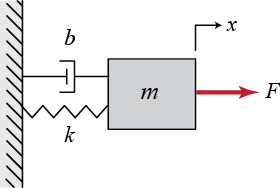

The state transition matrix is given as 


$$
\mathbf{\dot{x}} = \left[ \begin{array}{c} \dot{x} \\ \ddot{x} \end{array} \right] = \left[ \begin{array}{cc} 0 & 1 \\ -\frac{k}{m}  & -\frac{b}{m} \end{array} \right] \left[ \begin{array}{c} x \\ \dot{x} \end{array} \right] $$


with $F=0$. We can consider the initial condition where the mass is displaced by 1 meter and is at rest. 

m = 60; 
k = 60; 
b = 20; 
A = [0,1;-k/m,-b/m]; 
syms s 
Phi = ilaplace( inv(s*eye(2)-A))

$$Phi = \begin{array}{l} \left(\begin{array}{cc} {\mathrm{e}}^{-\frac{t}{6}}\,\left(\cos\left(\frac{\sqrt{35}\,t}{6}\right)+\frac{\sqrt{35}\,\sin\left(\frac{\sqrt{35}\,t}{6}\right)}{35}\right) & \sigma_{1}\\ -\sigma_{1} & {\mathrm{e}}^{-\frac{t}{6}}\,\left(\cos\left(\frac{\sqrt{35}\,t}{6}\right)-\frac{\sqrt{35}\,\sin\left(\frac{\sqrt{35}\,t}{6}\right)}{35}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{6\,\sqrt{35}\,{\mathrm{e}}^{-\frac{t}{6}}\,\sin\left(\frac{\sqrt{35}\,t}{6}\right)}{35} \end{array}$$

x0 = [1;0]; 
x = Phi*x0

$$x = \left(\begin{array}{c} {\mathrm{e}}^{-\frac{t}{6}}\,\left(\cos\left(\frac{\sqrt{35}\,t}{6}\right)+\frac{\sqrt{35}\,\sin\left(\frac{\sqrt{35}\,t}{6}\right)}{35}\right)\\ -\frac{6\,\sqrt{35}\,{\mathrm{e}}^{-\frac{t}{6}}\,\sin\left(\frac{\sqrt{35}\,t}{6}\right)}{35} \end{array}\right)$$

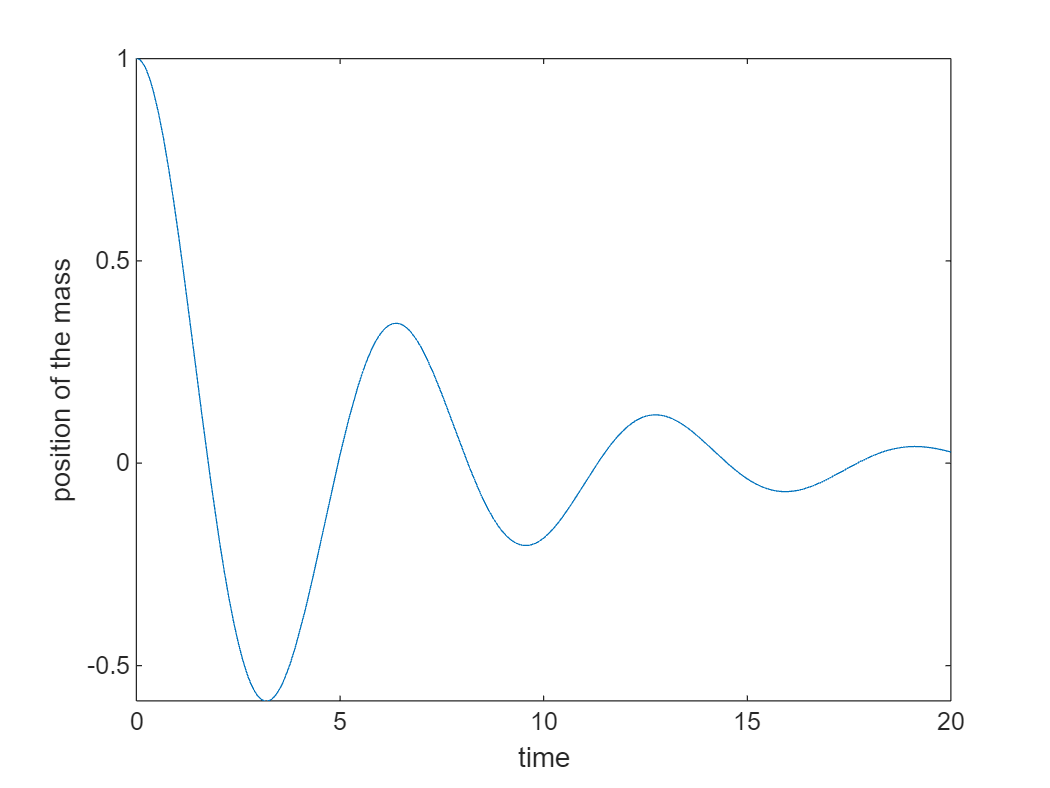

fplot(x(1),[0,20])
xlabel('time'); 
ylabel('position of the mass'); 

**Reflect:**

- What should happen to the above plot if you increase the damping coefficient? 

- Increase the damping coefficient and re-run this section. Is the result consistent with your answer to the previous question? 

**Enter your answers here: **

## **Mode**

What is a mode? 

Consider the equation 


$$\dot{\mathbf{x}} = A\mathbf{x}$$


- If its initial condition $\mathbf{x}(0)$ is along the direction of an eigenvector of A, the direction-preserving property of A guarantees that the velocity vector $\dot{\mathbf{x}}$ is along the same direction as $\mathbf{x}(0)$. 

- In this case, the entire state trajectory x(t) starting at x(0) can be expressed as 


$$\mathbf{x}(t) = e^{\lambda_it}\mathbf{x}(0) $$


where $\lambda_i$ is the eigenvalue corresponding to the eigenvector $\mathbf{x}(0)$. 

- This is essentially the behavior of a 1st order system embedded in an n-dimensional space

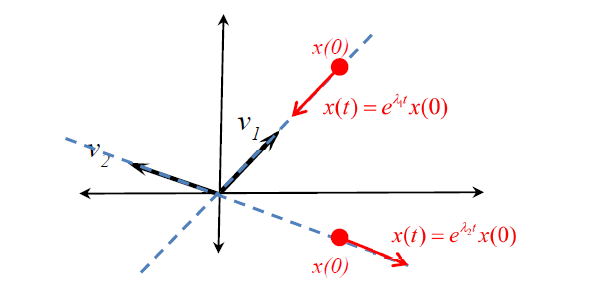

- Along this line of thinking, an n-dimensional system with n linearly independent eigenvectors can be thought of as a collection of n independent 1st-order systems. 

- Each of these 1st-order systems is a **mode** of the system.

### Expressing solutions in terms of modes

- If the initial state is not in one of the eigenvector directions, since the set of n eigenvectors is linearly independent, we can express the initial state $\mathbf{x}(0)$ as a sum of scaled eigenvectors as in  where k1,…,kn are scalars.


$$\mathbf{x}(0) = k_1 \mathbf{v}_1 + k_2 \mathbf{v}_2 + \cdots + k_n \mathbf{v}_n$$


- The output can then be expressed as 


$$\mathbf{x}(t) = k_1 e^{\lambda_1 t} \mathbf{v}_1 + k_2 e^{\lambda_2 t} \mathbf{v}_2 + \cdots + k_n e^{\lambda_n t}\mathbf{v}_n$$


- A mode is a distinct natural behavior (as opposed to a forced behavior by an input) of a system. Any natural response of a system can be expressed as a combination of these distinct responses.

### Exercise

Consider the system 


$$\left[ \begin{array}{c} \dot{x_1} \\ \dot{x_2} \end{array} \right]  = \left[ \begin{array}{cc} -1 & 2 \\
4  & 1

  \end{array}  \right] \left[ \begin{array}{c} x_1 \\ x_2 \end{array} \right]  $$


%compute the eigenvectors and eigenvalues of the matrix A 
A = [-1,2;4,1]; 
[v,d] = eig(A)

v =    -0.7071   -0.4472
    0.7071   -0.8944


d =     -3     0
     0     3


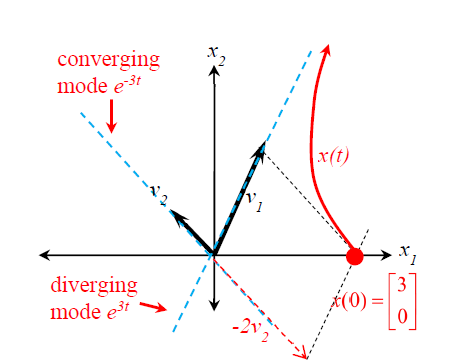

If the initial condition is [3;0], which is not an eigenvector, then 

%express x0 as a linear combination of eigenvectors x0 = c1*v_1 + c2*v_2
x0 = [3;0]; 
c = v\x0

c =    -2.8284
   -2.2361


c(1)*v(:,1) + c(2)*v(:,2)

ans =      3
     0


The state trajectory can then be given as 


$$\mathbf{x}(t) = c_1e^{-3t}v_1 + c_2e^{3t}v_2$$


If one of the modes is diverging, then the system trajectory will diverge (unstable). 

## Complex eigenvalue case

A = [-1,0,0; -1,0,-13; -1 1 -4]

A =     -1     0     0
    -1     0   -13
    -1     1    -4


[v,d] = eig(A)

v =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.7071 + 0.0000i
   0.9636 + 0.0000i   0.9636 + 0.0000i   0.7071 + 0.0000i
   0.1482 - 0.2224i   0.1482 + 0.2224i  -0.0000 + 0.0000i


d =   -2.0000 + 3.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -2.0000 - 3.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.0000 + 0.0000i


In this case, if the initial state is in the span of $v_1$($$v_x$
$) and $v_2$($$v_y$$), then the state trajectory will be confined to the 2 dimensional subspace 

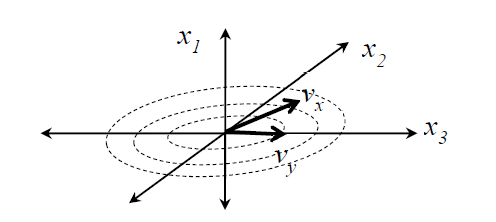

## Modal state representation

B = [0;0;0]; C = [1,0,0]; D = 0; 
ExSS = ss(A,B,C,D); 
ExSSmodal = modalreal(ExSS)

ExSSmodal =
 
  A = 
           x1      x2      x3
   x1      -2  0.6754       0
   x2  -13.32      -2       0
   x3       0       0      -1
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
 
  C = 
           x1      x2      x3
   y1       0       0  0.7071
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


### Example

- Consider the following system where three masses are connected by an elastic string fixed on both ends. 

- All masses are restricted to move up-and-down, i.e., along the y-axis. 

- Each mass is a 2nd order system so this entire system is 6th order. 

- This system has three distinct 2nd-order damped oscillatory modes.

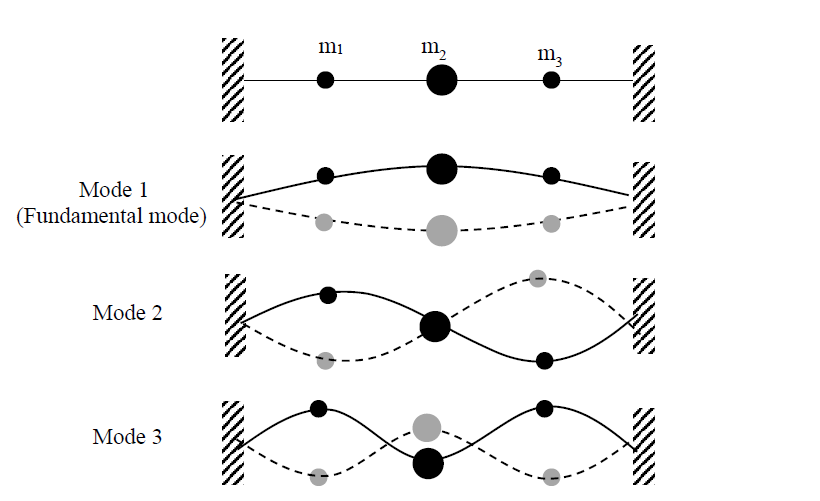

Note: If you disturb the balls into position of one of configurations above, the system will remain in the corresponding mode. 

Doc page for state space representation and coordinate transformation: 

https://www.mathworks.com/help/control/ug/canonical-state-space-realizations.html